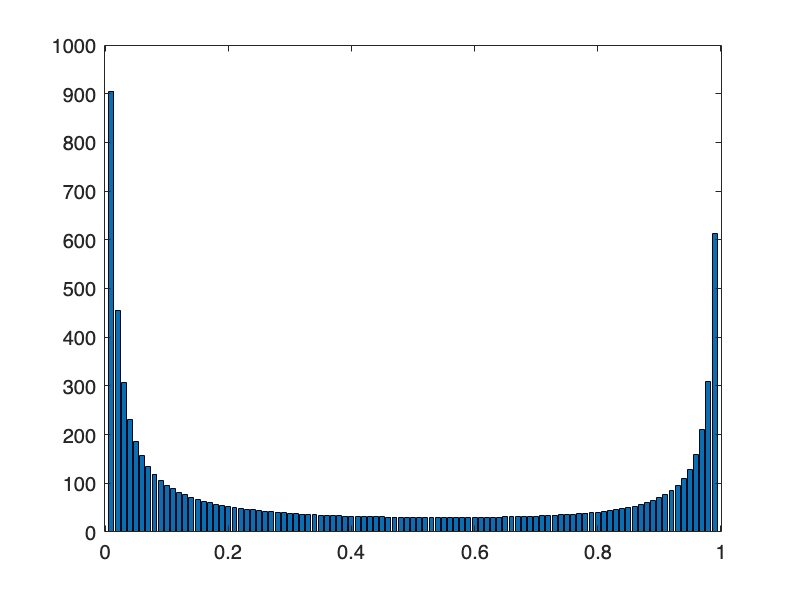

clear
trials = 100000;
distrubtion = [];

for p = 0.01:0.01:0.99
    walks = 0;
    for i = 1:trials
        Atx = 1;
        x = 2;
        y = 2;
        wet = 0;
        while(x >= 0 && y >= 0)
            rain = rand < p;
            if(Atx && rain)
                x = x - 1;
                y = y + 1;
            end
            if(~Atx && rain)
                x = x + 1;
                y = y - 1;
            end
        Atx = ~Atx;
        walks = walks + 1;
        end
    end
    distrubtion(end+1) = walks/trials;
end
bar(0.01:0.01:0.99, distrubtion)